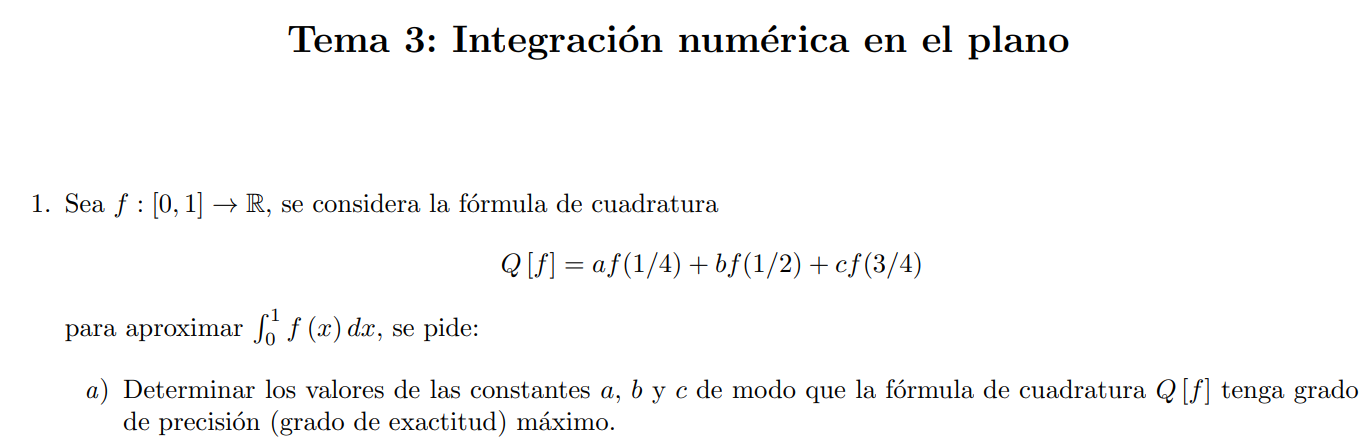

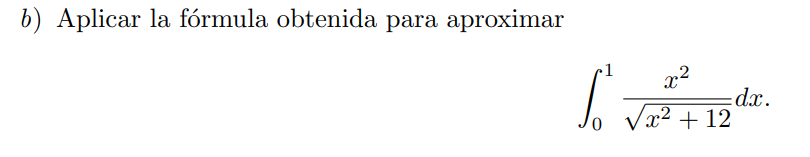

f=@(x) x.^2/sqrt(x.^2+12);
xi=[.25 .5 .75];
wi=[2/3 -1/3 2/3];
sum(wi.*f(xi))

ans =    0.083681977075538


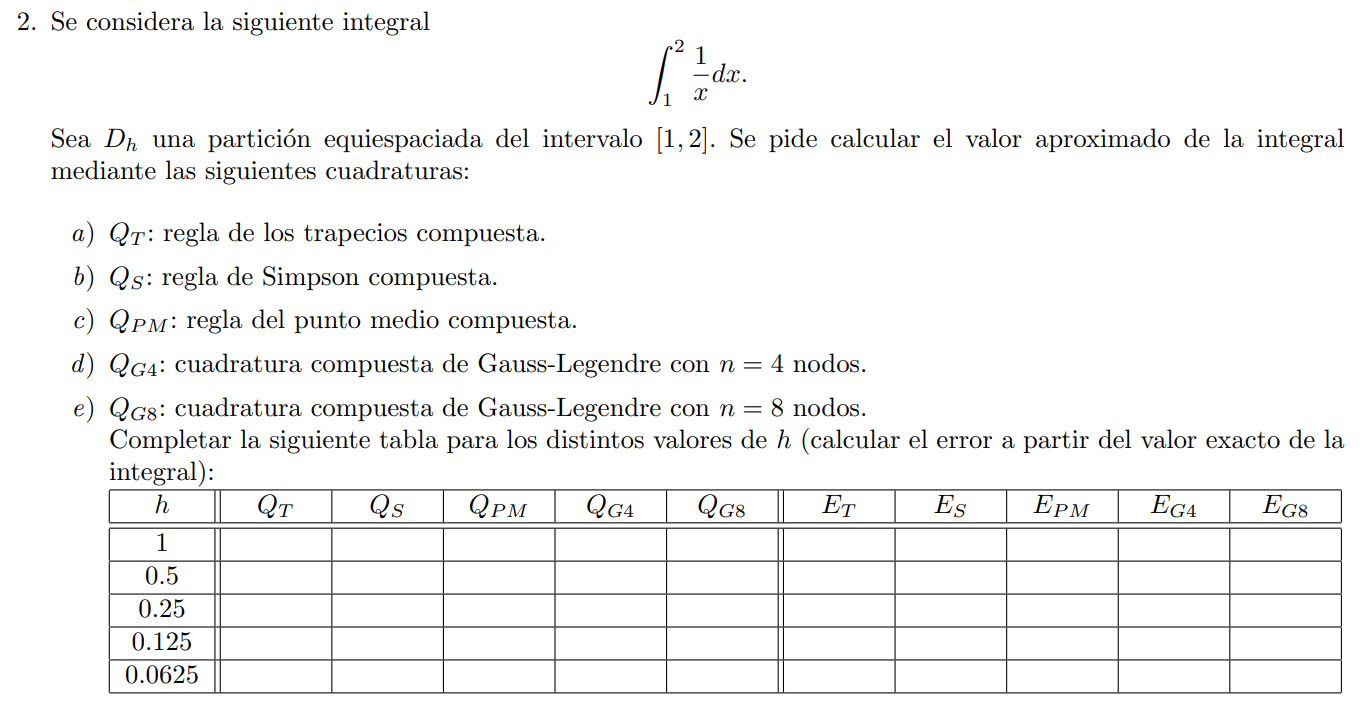

mallado=[1 0.5 0.25 0.125 0.0625];
a=1; b=2;
f=@(x) 1./x;
valor_real=integral(f,a,b);
for k=1:length(mallado)
    h=mallado(k); %le vamos dando los distintos valores de h
    n=(b-a)/h;
    xi=a:h:b;

    %Regla de simpson compuesta
    ws=ones(1,n+1);
    ws(3:2:end-2)=2;
    ws(2:2:end-1)=4;
    Qs=sum(ws.*f(xi));

    %Regla del trapecio compuesta
    wt=2*ones(1,n+1);
    wt(1)=1;
    wt(end)=1;
    Qt=sum(wt.*f(xi));

    Qs
    Es=abs(Qs-valor_real)

    Qt
    Et=abs(Qt-valor_real)


end

Qs = 1.5000

Es = 0.8069

Qt = 1.5000

Et = 0.8069

Qs = 4.1667

Es = 3.4735

Qt = 2.8333

Et = 2.1402

Qs = 8.3190

Es = 7.6259

Qt = 5.5762

Et = 4.8830

Qs = 16.6357

Es = 15.9426

Qt = 11.1059

Et = 10.4128

Qs = 33.2711

Es = 32.5779

Qt = 22.1885

Et = 21.4954

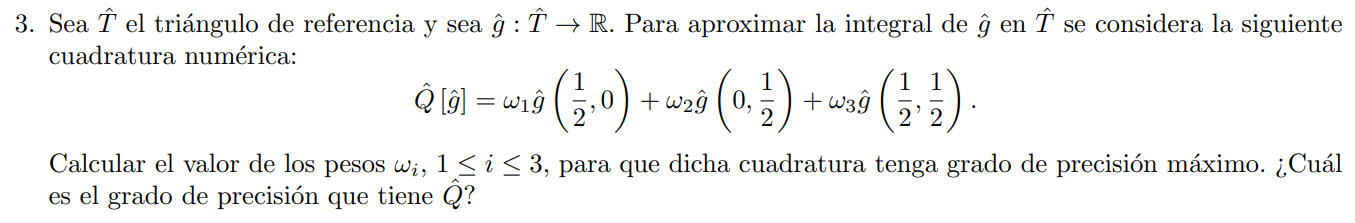

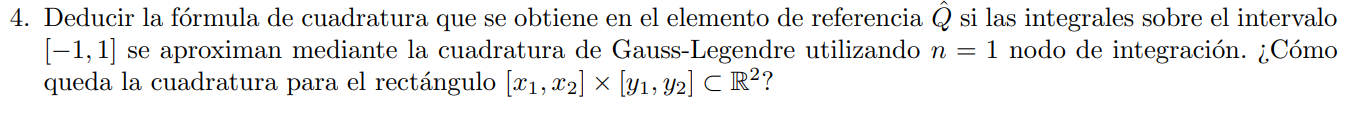

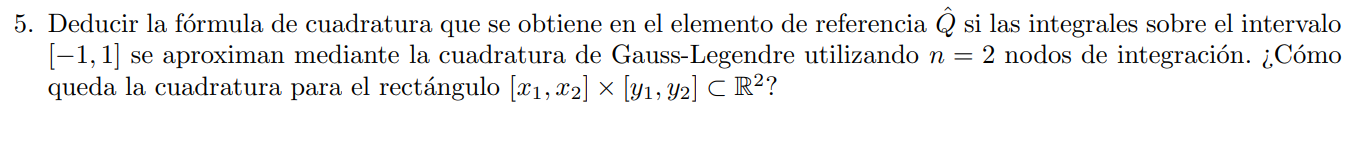

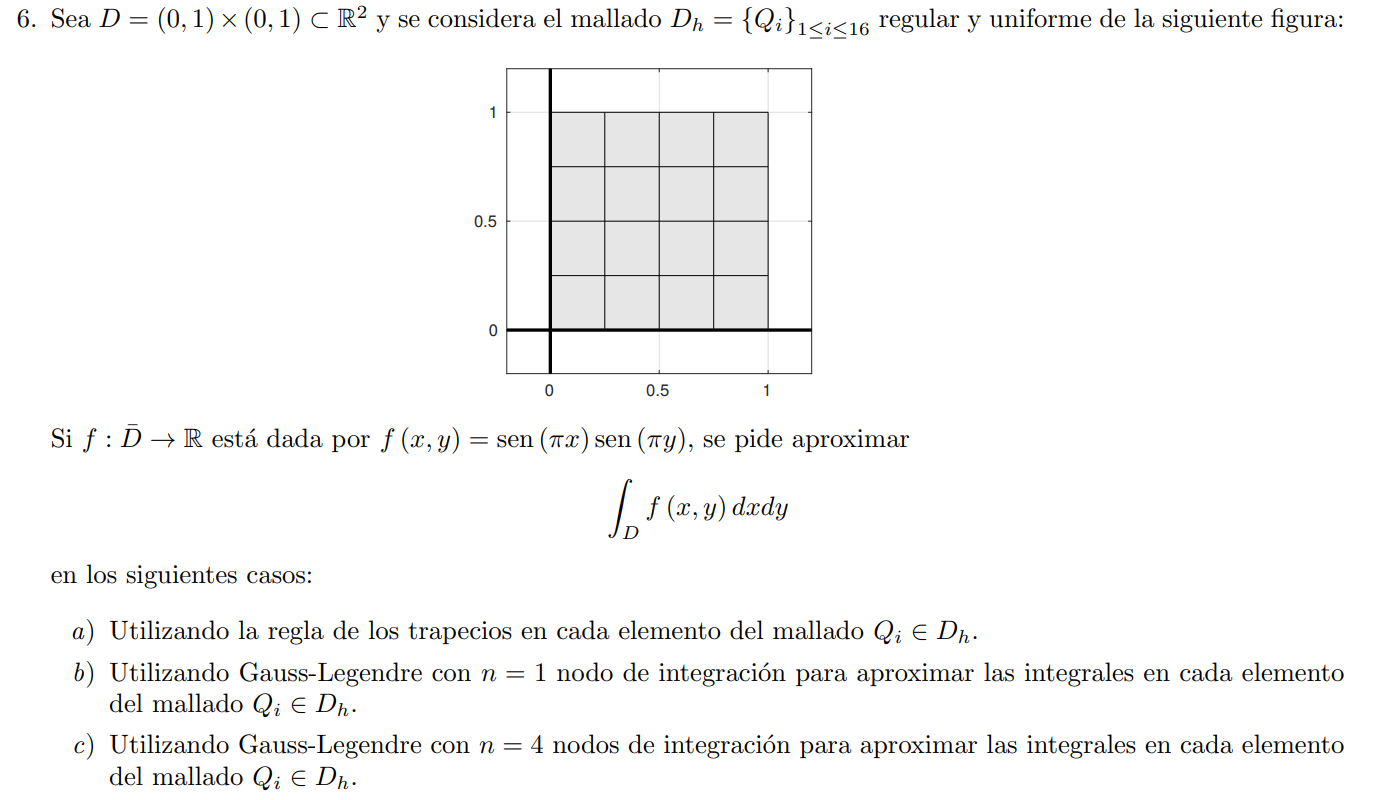

%vamos a reutilizar el código del ejercicio 10 que es para un punto y
%triángulos y hay que adaptarlo a trapecios y cuadrados
clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);
%f=@(x,y) 1;

%ahora no estamos dibujando entonces en algun lado hay que poner los xi e
%yi

%voy a probar a poner a lo bruto las coordenadas

%tabla de conexiones, cada columna es el nodo, tendría que haber
%4 filas por cada vértice
t=[1 2 3 4 6 7 8 9 11 12 13 14 16 17 18 19;
    2 3 4 5 7 8 9 10 12 13 14 15 17 18 19 20;
    7 8 9 10 12 13 14 15 17 18 19 20 22 23 24 25;
    6 7 8 9 11 12 13 14 16 17 18 19 21 22 23 24];
%tabla de coordenadas
p=[0 .25 .5 .75 1 0 .25 .5 .75 1 0 .25 .5 .75 1 0 .25 .5 .75 1 ...
    0 .25 .5 .75 1;
    0 0 0 0 0 .25 .25 .25 .25 .25 .5 .5 .5 .5 .5 .75 .75 .75 .75 .75 ...
    1 1 1 1 1];

%elem=t(1:4,:)';
elem=t';
xi=p(1,:);
yi=p(2,:);

%Xg=[1/3;1/3]; %esto no sé de donde salía en el de los triángulos
%creo que ahora este es mi Xg
Xg=[-1 -.5 0 .5 1 -1 -.5 0 .5 1 -1 -.5 0 .5 1 -1 -.5 0 .5 1 ...
    -1 -.5 0 .5 1;
    -1 -1 -1 -1 -1 -.5 -.5 -.5 -.5 -.5 0 0 0 0 0 .5 .5 .5 .5 .5 ...
    1 1 1 1 1];

Ne=length(elem); %los pongo a lo bruto??? la gracia está en que si consigo
%saber que es t y p ya no hace falta

area_total=0;
Qf=0;

for i=1:Ne
    X1=p(:,elem(i,1));    
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));
    X4=p(:,elem(i,4)); %hay 4 vértices

%     bi=X1;
%     Ai=[X2-X1 X3-X1]; %al ser cuadrados aquí hay que cambiar algo
%     X=bi+Ai*Xg;
    
    %Creo que así sería para cuadrados
    bi=0.5.*(X1+X3);
    Ai=0.5.*[X2-X1 X3-X2];
    X=bi+Ai*Xg;


    %area=0.5*abs(det(Ai));
    %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
    area=4*abs(det(Ai));

    %Qf=Qf+area*f(X(1),X(2)); %en el parntesis tengo que 
    % poner la cuadratura esto es lo que debo cambiar
    %en trapecios es f(a1)+f(a2)+f(a3)+f(a4) que son los vértices
    %f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))+f(X4(1),X4(2));
    Qf=Qf+area*0.25*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))+f(X4(1),X4(2)));
    area_total=area_total+area;
end

Qf/area_total

ans =    0.364276695296637


%la real
q = integral2(f,0,1,0,1)

q =    0.405284734552890


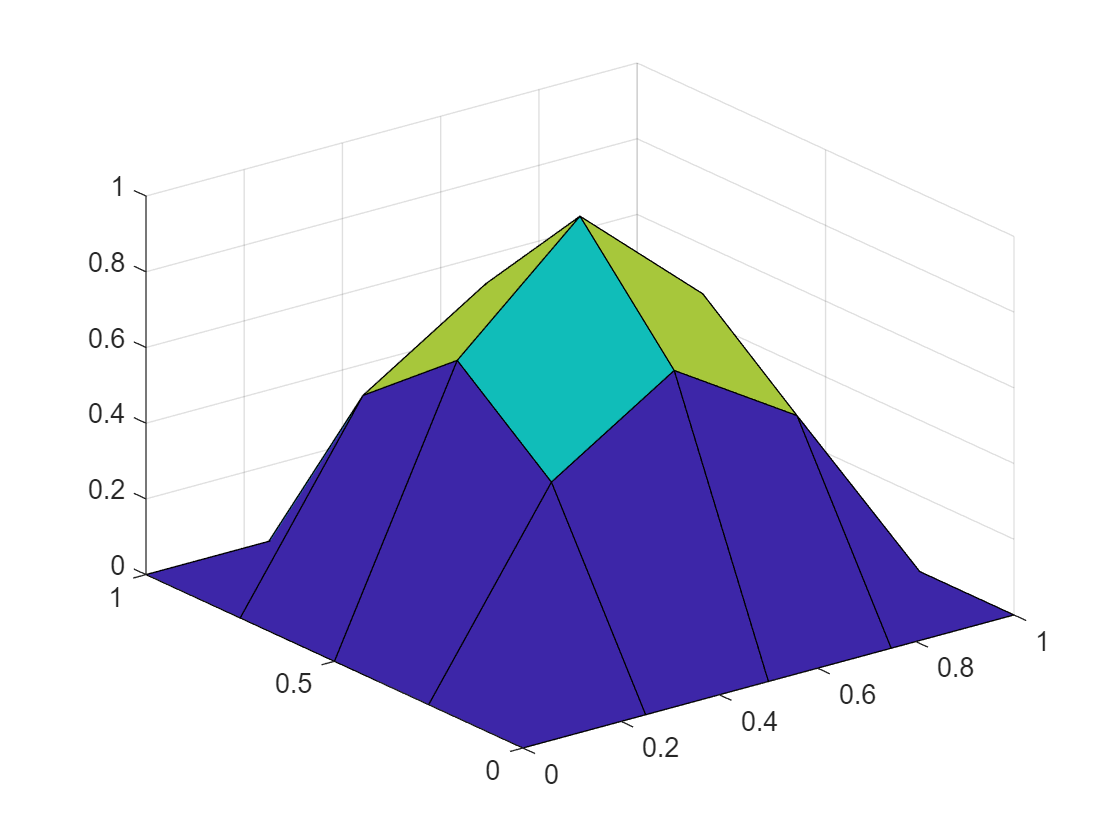

trisurf(elem,xi,yi,f(xi,yi)) %no vale la 3, hay que poner la elem

clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);

mallado=[0.25 0.125 0.0625];
for k=1:length(mallado)
h=mallado(k);
xi=0:h:1;
yi=0:h:1;



area_total=0;
Qf=0;

for i=1:length(xi)-1
    for j=1:length(yi)-1
        X1=[xi(i);yi(j)];    
        X2=[xi(i+1);yi(j)];
        X3=[xi(i+1);yi(j+1)];
        X4=[xi(i);yi(j+1)];

        

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        Qf=Qf+area*0.25*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))...
            +f(X4(1),X4(2)));
        area_total=area_total+area;

    end

end
Qf/area_total
end

ans =    0.364276695296637


ans =    0.394908474517003


ans =    0.402683081718037


%sale igual que de la forma chunga
%Viva!!!

clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);

mallado=[0.25 0.125 0.0625];
for k=1:length(mallado)
h=mallado(k);
xi=0:h:1;
yi=0:h:1;



area_total=0;
Qf=0;

for i=1:length(xi)-1
    for j=1:length(yi)-1

%         X1=[xi(i);yi(j)];    
%         X2=[xi(i+1);yi(j)];
%         X3=[xi(i+1),yi(j+1)];
%         X4=[xi(i),yi(j+1)];

        X0=[xi(i)+h/2;yi(j)+h/2];

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        Qf=Qf+area*0.25*4*(f(X0(1),X0(2)));
        area_total=area_total+area;

    end

end
Qf/area_total
end

ans =    0.426776695296637


ans =    0.410533474517003


ans =    0.406589331718037




%la real
q = integral2(f,0,1,0,1)

q =    0.405284734552890


%trisurf(elem,xi,yi,f(xi,yi))


%GL n=4
clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);

mallado=[0.25 0.125 0.0625];
for k=1:length(mallado)
h=mallado(k);
xi=0:h:1;
yi=0:h:1;



area_total=0;
Qf=0;

for i=1:length(xi)-1
    for j=1:length(yi)-1
        X1=[xi(i)+h/sqrt(3);yi(j)+h/sqrt(3)];    
        X2=[xi(i+1)-h/sqrt(3);yi(j)+h/sqrt(3)];
        X3=[xi(i+1)-h/sqrt(3);yi(j+1)-h/sqrt(3)];
        X4=[xi(i)+h/sqrt(3);yi(j+1)-h/sqrt(3)];

        

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        %para n=4 los pesos son 1 viva!!!

        Qf=Qf+area*0.25*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))...
            +f(X4(1),X4(2)));
        area_total=area_total+area;

    end

end
Qf/area_total
end

ans =    0.425203546599088


ans =    0.410154806668768


ans =    0.406495552625566



%G-L n=16

clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);
%f=@(x,y) 1;

%ahora no estamos dibujando entonces en algun lado hay que poner los xi e
%yi

%voy a probar a poner a lo bruto las coordenadas

%tabla de conexiones, cada columna es el nodo, tendría que haber
%4 filas por cada vértice
t=[1 2 3 4 6 7 8 9 11 12 13 14 16 17 18 19;
    2 3 4 5 7 8 9 10 12 13 14 15 17 18 19 20;
    7 8 9 10 12 13 14 15 17 18 19 20 22 23 24 25;
    6 7 8 9 11 12 13 14 16 17 18 19 21 22 23 24];
%tabla de coordenadas
p=[0 .25 .5 .75 1 0 .25 .5 .75 1 0 .25 .5 .75 1 0 .25 .5 .75 1 ...
    0 .25 .5 .75 1;
    0 0 0 0 0 .25 .25 .25 .25 .25 .5 .5 .5 .5 .5 .75 .75 .75 .75 .75 ...
    1 1 1 1 1];

%elem=t(1:4,:)';
elem=t';
xi=p(1,:);
yi=p(2,:);

%Xg=[1/3;1/3]; %esto no sé de donde salía en el de los triángulos
%creo que ahora este es mi Xg
a1=0.8611363115940526;
a2=0.3399810435848563;
Xg=[-a1 -a2 a2 a1 -a1 -a2 a2 a1 -a1 -a2 a2 a1 -a1 -a2 a2 a1;
    -a1 -a1 -a1 -a1 -a2 -a2 -a2 -a2 a2 a2 a2 a2 a1 a1 a1 a1];

Ne=length(elem); %los pongo a lo bruto??? la gracia está en que si consigo
%saber que es t y p ya no hace falta

area_total=0;
Qf=0;

for i=1:Ne
    X1=p(:,elem(i,1));    
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));
    X4=p(:,elem(i,4)); %hay 4 vértices

%     bi=X1;
%     Ai=[X2-X1 X3-X1]; %al ser cuadrados aquí hay que cambiar algo
%     X=bi+Ai*Xg;
    
    %Creo que así sería para cuadrados
    bi=0.5.*(X1+X3);
    Ai=0.5.*[X2-X1 X3-X2];
    X=bi+Ai*Xg;


    %area=0.5*abs(det(Ai));
    %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
    
    %AQUÍ ESTABA EL ERROR
    area=4*abs(det(Ai));
    %area=abs(det(Ai));

    %Qf=Qf+area*f(X(1),X(2)); %en el parntesis tengo que 
    % poner la cuadratura esto es lo que debo cambiar
    %Aquí iría la cuadratura para Gauss-Legendre
    %los pesos son:
    w=[0.3478548451374538 0.6521451548625461];
    q1=w(1)*(w(1)*f(X(1,1),X(2,1))+w(2)*f(X(1,2),X(2,2))+w(2)*f(X(1,3),X(2,3))+w(1)*f(X(1,4),X(2,4))); 
    q2=w(2)*(w(1)*f(X(1,5),X(2,5))+w(2)*f(X(1,6),X(2,6))+w(2)*f(X(1,7),X(2,7))+w(1)*f(X(1,8),X(2,8)));
    q3=w(2)*(w(1)*f(X(1,9),X(2,9))+w(2)*f(X(1,10),X(2,10))+w(2)*f(X(1,11),X(2,11))+w(1)*f(X(1,12),X(2,12)));
    q4=w(1)*(w(1)*f(X(1,13),X(2,13))+w(2)*f(X(1,14),X(2,14))+w(2)*f(X(1,15),X(2,15))+w(1)*f(X(1,16),X(2,16))); 
   
   
   
    Qf=Qf+area*.25*(q1+q2+q3+q4);
    area_total=area_total+area;
end

Qf/area_total

ans =    0.405284734501880


%la real
q = integral2(f,0,1,0,1)

q =    0.405284734552890


trisurf(elem,xi,yi,f(xi,yi)) %no vale la 3, hay que poner la elem

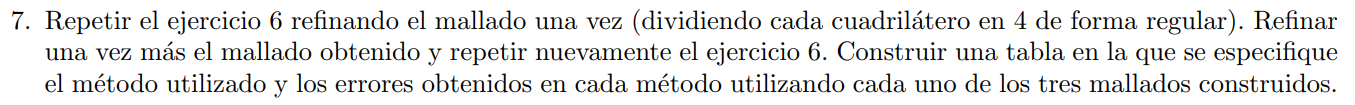

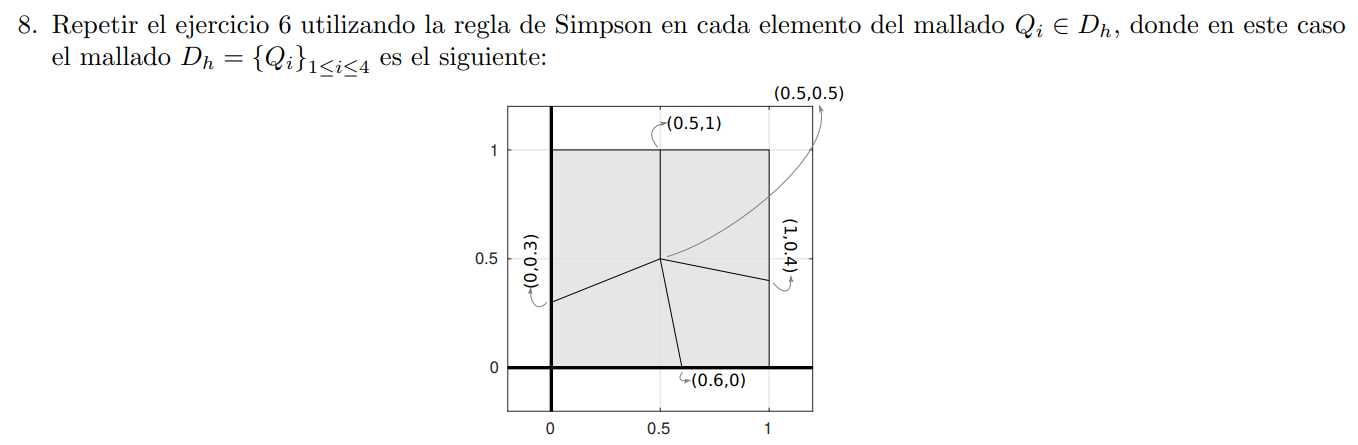

%vamos a reutilizar el código del ejercicio 10 que es para un punto y
%triángulos y hay que adaptarlo a trapecios y cuadrados
clear

format long
f=@(x,y) sin(pi*x).*sin(pi*y);

%ahora no estamos dibujando entonces en algun lado hay que poner los xi e
%yi

%voy a probar a poner a lo bruto las coordenadas

%tabla de conexiones, cada columna es el nodo, tendría que haber
%4 filas por cada vértice
t=[1 2 3 4;
    2 3 6 5;
    5 6 9 8;
    4 5 8 7];
%tabla de coordenadas
p=[0 .6 1 0 .5 1 0 .5 1;
    0 0 0 .3 .5 .4 1 1 1];

%elem=t(1:4,:)';
elem=t';
xi=p(1,:);
yi=p(2,:);

%Xg=[1/3;1/3]; %esto no sé de donde salía en el de los triángulos
%creo que ahora este es mi Xg
Xg=[-1 -.5 0 .5 1 -1 -.5 0 .5 1 -1 -.5 0 .5 1 -1 -.5 0 .5 1 ...
    -1 -.5 0 .5 1;
    -1 -1 -1 -1 -1 -.5 -.5 -.5 -.5 -.5 0 0 0 0 0 .5 .5 .5 .5 .5 ...
    1 1 1 1 1];

Ne=length(elem); %los pongo a lo bruto??? la gracia está en que si consigo
%saber que es t y p ya no hace falta

area_total=0;
Qf=0;

for i=1:Ne
    X1=p(:,elem(i,1));    
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));
    X4=p(:,elem(i,4)); %hay 4 vértices

    X5=0.5*(X1+X2);
    X6=0.5*(X2+X3);
    X7=0.5*(X4+X3);
    X8=0.5*(X1+X4);
    X9=0.5*(X8+X6);

%     bi=X1;
%     Ai=[X2-X1 X3-X1]; %al ser cuadrados aquí hay que cambiar algo
%     X=bi+Ai*Xg;
    
    %Creo que así sería para cuadrados
    bi=0.5.*(X1+X3);
    Ai=0.5.*[X2-X1 X3-X2];
    X=bi+Ai*Xg;


    %area=0.5*abs(det(Ai));
    %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
    area=4*abs(det(Ai));

    %Qf=Qf+area*f(X(1),X(2)); %en el parntesis tengo que 
    % poner la cuadratura esto es lo que debo cambiar
    %en trapecios es f(a1)+f(a2)+f(a3)+f(a4) que son los vértices
    %f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))+f(X4(1),X4(2));
    %ahora para simpson mi cuadratura será:
    % 0.5*(f(a1)+f(a2)+f(a3)+f(a4))+4/9*(f(a5)+f(a6)+f(a7)+f(a8))+16/9*f(a9)
    Qf=Qf+area*0.25*(0.5*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))+f(X4(1),X4(2))) ...
        +4/9*(f(X5(1),X5(2))+f(X6(1),X6(2))+f(X7(1),X7(2))+f(X8(1),X8(2))) ...
        +16/9*f(X9(1),X9(2)));
    area_total=area_total+area;
end

Qf/area_total

ans =    0.494015405657343


%la real
q = integral2(f,0,1,0,1)

q =    0.405284734552890


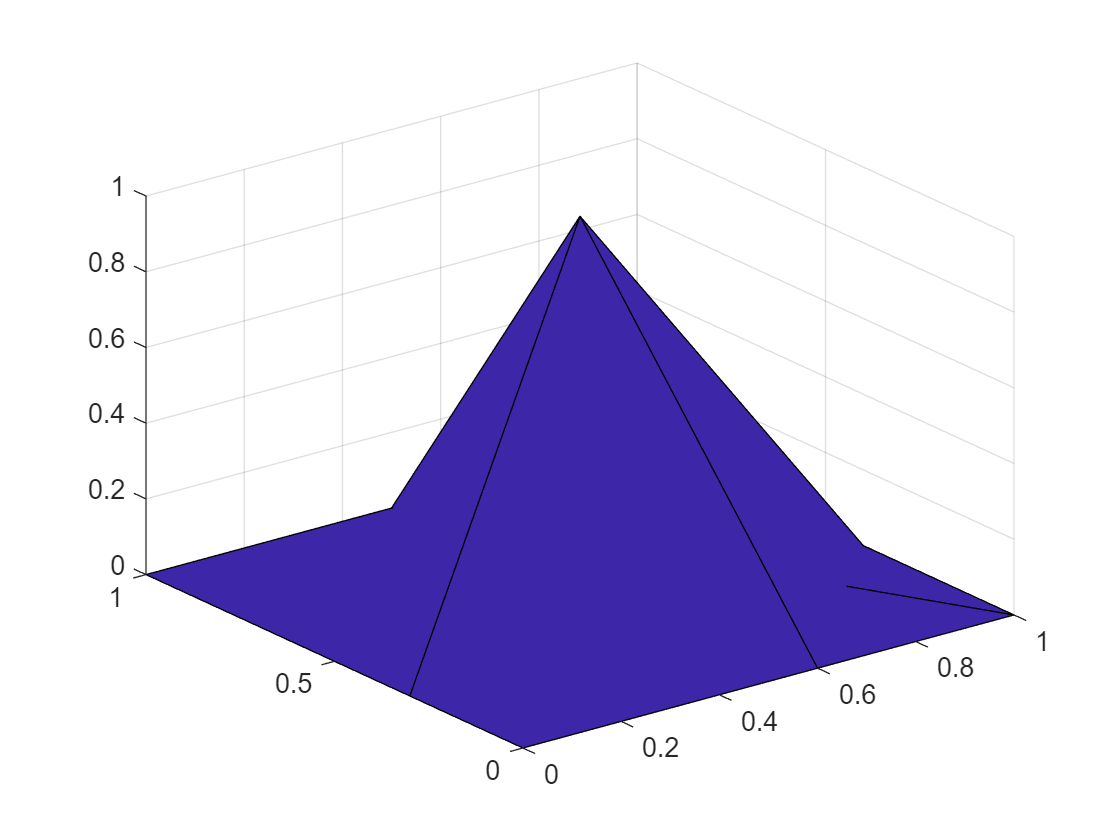

trisurf(elem,xi,yi,f(xi,yi)) %no vale la 3, hay que poner la elem

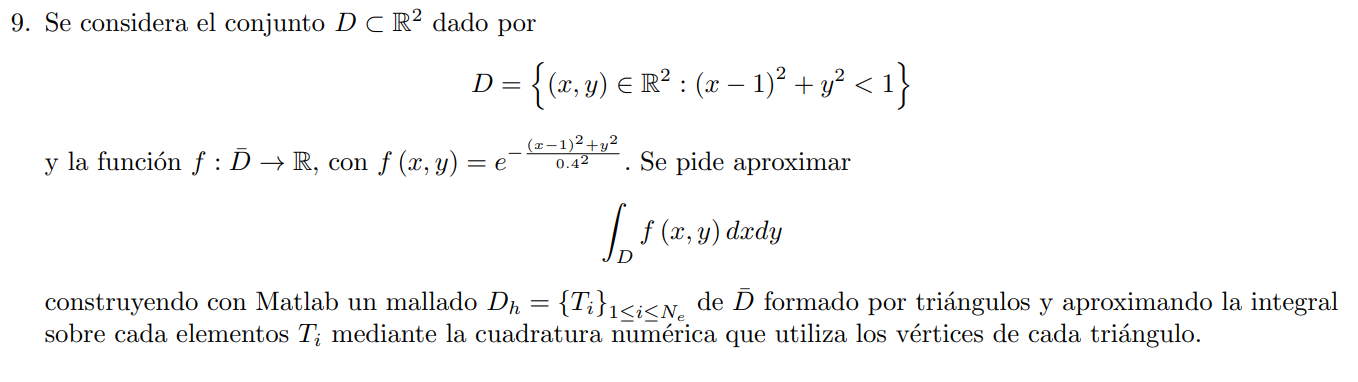

%vamos a reutilizar el código del ejercicio 10 que es para un punto e ir
%adantándolo a la cuadratura para los 3 vértices
f=@(x,y) exp(-((x-1).^2+y.^2)./0.4^2);

%preguntar a Pedro si hay alguna forma de guardar el dibujito y abrirlo
%desde el código

elem=t(1:3,:)';
xi=p(1,:);
yi=p(2,:);

%Xg=[1/3;1/3]; %sigo sin saber de donde sale esto
Xg=[0 1 0;0 0 1]; %creo que es esto pero no estoy segura
Ne=length(elem);

area_total=0;
Qf=0;

for i=1:Ne
    X1=p(:,elem(i,1));    
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));

    bi=X1;
    Ai=[X2-X1 X3-X1];
    X=bi+Ai*Xg;


    area=0.5*abs(det(Ai));
    %Qf=Qf+area*f(X(1),X(2)); %en el parntesis tengo que 
    % poner la cuadratura esto es lo que debo cambiar
    %como son 3 vértices: 1/6*(f(a1)+f(a2)+f(a3))
    Qf=Qf+area*1/6*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2)));
    area_total=area_total+area;
end

Qf/area_total

ans =    0.080015990110539


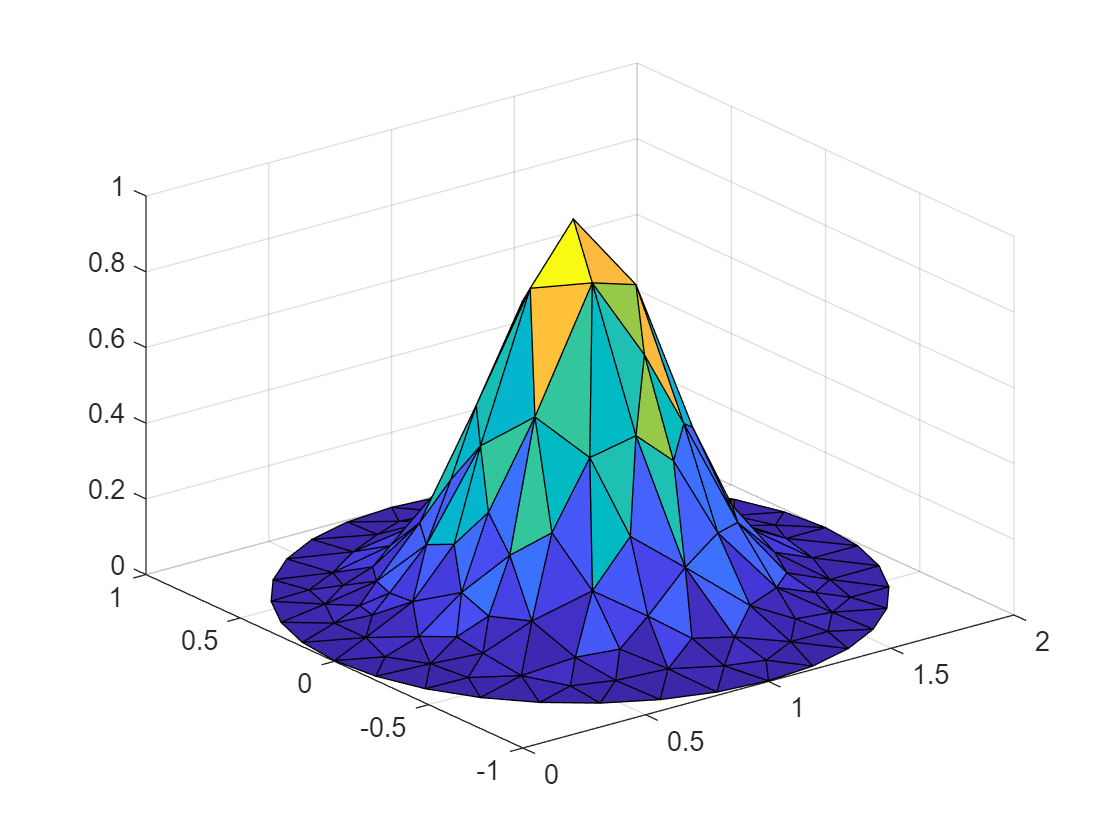

trisurf(elem,xi,yi,f(xi,yi)) %no vale la 3, hay que poner la elem

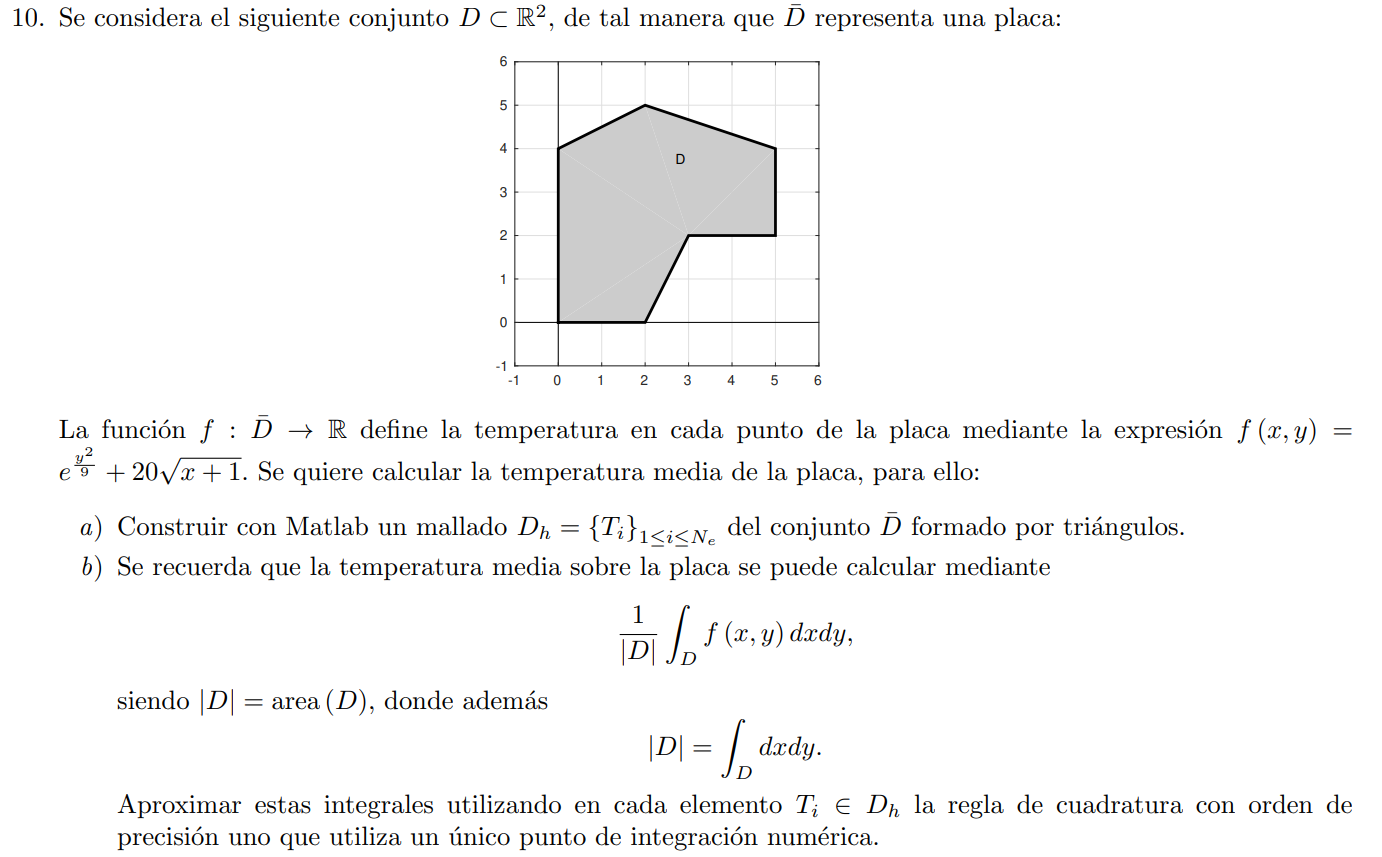

f=@(x,y) exp(y.^2/9)+20*sqrt(x+1);

elem=t(1:3,:)';
xi=p(1,:);
yi=p(2,:);

Xg=[1/3;1/3];
Ne=length(elem);

area_total=0;
Qf=0;

for i=1:Ne
    X1=p(:,elem(i,1));    
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));

    bi=X1;
    Ai=[X2-X1 X3-X1];
    X=bi+Ai*Xg;


    area=0.5*abs(det(Ai));
    Qf=Qf+area*f(X(1),X(2)); %en el parntesis tengo que 
    % poner la cuadratura calcular el área
    area_total=area_total+area;
end

Qf/area_total
trisurf(elem,xi,yi,f(xi,yi)) %no vale la 3, hay que poner la elem

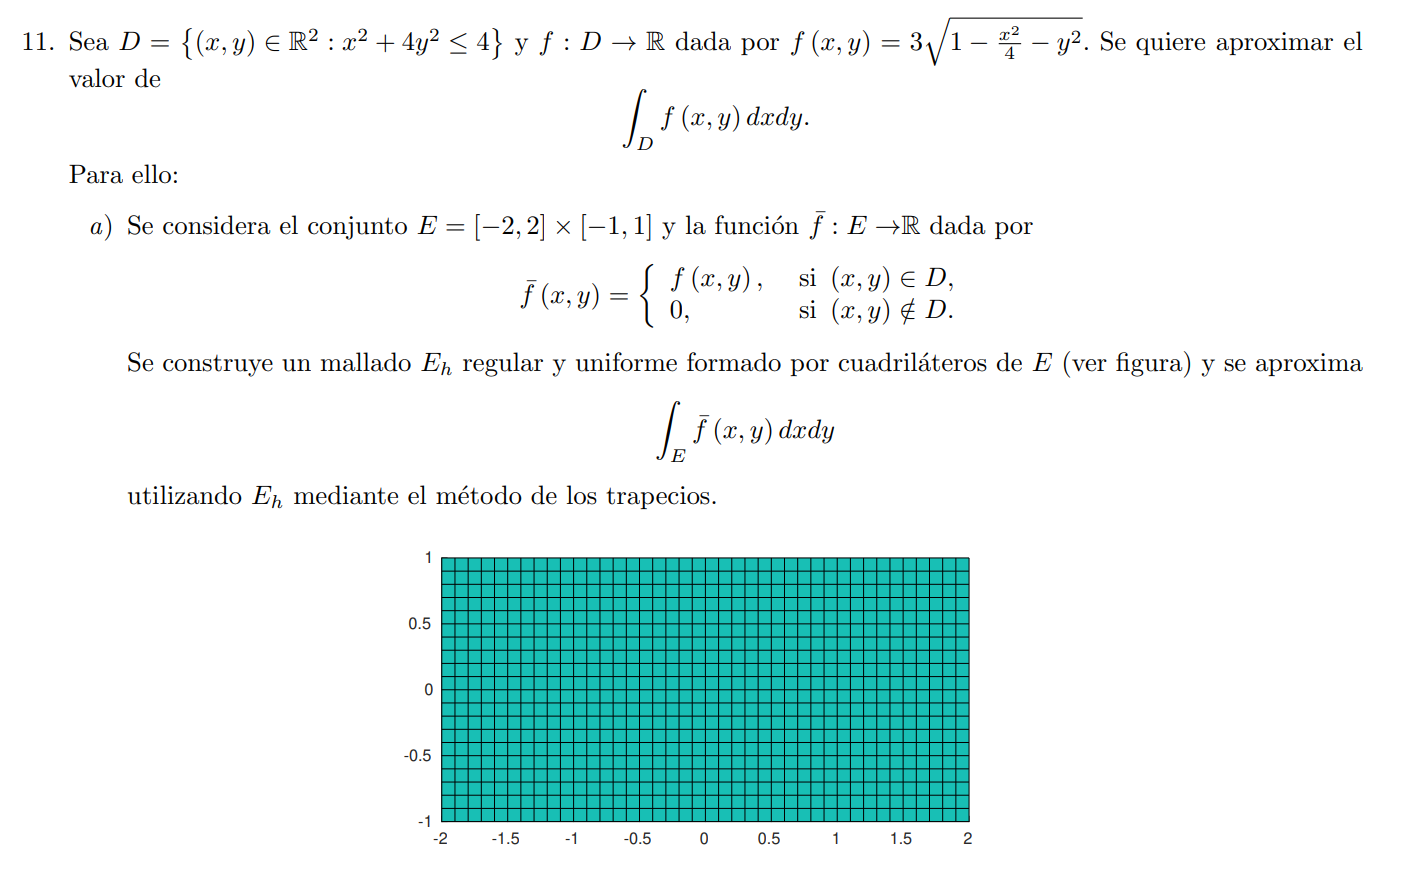

clear

format long
f=@(x,y) 3*sqrt(1-0.25*x.^2-y.^2);



h=0.5/5;
xi=-2:h:2;
yi=-1:h:1;



area_total=0;
Qf=0;

for i=1:length(xi)-1
    for j=1:length(yi)-1

        if (xi(i)^2+4*yi(j)^2>=4)
            
        
        
        X1=[xi(i);yi(j)];    
        X2=[xi(i+1);yi(j)];
        X3=[xi(i+1);yi(j+1)];
        X4=[xi(i);yi(j+1)];


        

        

        %para cuadrados det(JFi)=area(Qi)/4 luego el área será:
        area=h^2;

        Qf=Qf+area*0.25*(f(X1(1),X1(2))+f(X2(1),X2(2))+f(X3(1),X3(2))...
            +f(X4(1),X4(2)));
        area_total=area_total+area;
        end
        

    end

end
Qf/area_total

ans =   0.120184141487570 + 1.287597658073690i


abs(Qf/area_total)

ans =    1.293194477618101
